clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[0;12.852;17.646];
u31=[0;0;1];
r2=[0;12.852;38.821];
u32=[0;0;-1];
r3=[11.130;6.426;3.529];
u33=[0;0;1];
r4=[11.130;6.426;24.704];
u34=[0;0;-1];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];


hold on
axis([0 15 0 15]);
for R1=2:0.3:13 %离心率
    R3=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     2.0000   10.5800    1.0014


ans =     2.3000   10.5800    1.0014


ans =     2.6000   10.5800    1.0014


ans =     2.9000   10.5800    1.0014


ans =     3.2000   10.5800    1.0014


ans =     3.5000   10.5800    1.0014


ans =     3.8000   10.5800    1.0014


ans =     4.1000   10.5800    1.0014


ans =     4.4000   10.5800    1.0014


ans =     4.7000   10.5800    1.0014


ans =     5.0000   10.5800    1.0014


ans =     5.3000   10.5800    1.0014


ans =     5.6000   10.5800    1.0014


ans =     5.9000   10.5800    1.0014


ans =     6.2000   10.5800    1.0014


ans =     6.5000   10.5800    1.0014


ans =     6.8000   10.5800    1.0014


ans =     7.1000   10.5800    1.0014


ans =     7.4000   10.5800    1.0014


ans =     7.7000   10.5800    1.0014


ans =     8.0000   10.5800    1.0014


ans =     8.3000   10.5800    1.0014


ans =     8.6000   10.5800    1.0014


ans =     8.9000   10.5800    1.0014


ans =     9.2000   10.5800    1.0014


ans =     9.5000   10.5800    1.0014


ans =     9.8000   10.5800    1.0014


ans =    10.1000   10.5800    1.0014


ans =    10.4000   10.5800    1.0014


ans =    10.7000   10.5800    1.0014


ans =    11.0000   10.5800    1.0014


ans =    11.3000   10.5800    1.0014


ans =    11.6000   10.5800    1.0014


ans =    11.9000   10.5800    1.0014


ans =    12.2000   10.5800    1.0014


ans =    12.5000   10.5800    1.0014


ans =    12.8000   10.5800    1.0014



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R1=7.3:0.3:13 %离心率
    R3=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     7.3000   14.8700    1.0002


ans =     7.6000   13.2100    1.0004


ans =     7.9000   12.1300    1.0002


ans =     8.2000   11.3600    1.0002


ans =     8.5000   10.7800    1.0003


ans =     8.8000   10.3300    1.0001


ans =     9.1000    9.9600    1.0009


ans =     9.4000    9.6700    1.0001


ans =     9.7000    9.4200    1.0003


ans =    10.0000    9.2100    1.0003


ans =    10.3000    9.0300    1.0002


ans =    10.6000    8.8700    1.0008


ans =    10.9000    8.7300    1.0013


ans = 1×3
   11.2000    8.6100    1.0013


ans = 1×3
   11.5000    8.5100    1.0002


ans = 1×3
   11.8000    8.4100    1.0010


ans = 1×3
   12.1000    8.3300    1.0001


ans = 1×3
   12.4000    8.2500    1.0006


ans = 1×3
   12.7000    8.1800    1.0006


ans = 1×3
   13.0000    8.1100    1.0018



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')

for R3=5:0.3:13 %离心率
    R1=7;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    9.0700    5.0000    1.0001


ans = 1×3
    8.6100    5.3000    1.0004


ans = 1×3
    8.2700    5.6000    1.0009


ans = 1×3
    8.0100    5.9000    1.0014


ans = 1×3
    7.8100    6.2000    1.0010


ans = 1×3
    7.6500    6.5000    1.0004


ans = 1×3
    7.5100    6.8000    1.0015


ans = 1×3
    7.4000    7.1000    1.0011


ans = 1×3
    7.3100    7.4000    1.0002


ans = 1×3
    7.2200    7.7000    1.0022


ans = 1×3
    7.1600    8.0000    1.0001


ans = 1×3
    7.0900    8.3000    1.0022


ans = 1×3
    7.0400    8.6000    1.0015


ans = 1×3
    6.9900    8.9000    1.0023


ans = 1×3
    6.9500    9.2000    1.0020


ans = 1×3
    6.9200    9.5000    1.0003


ans = 1×3
    6.8800    9.8000    1.0020


ans = 1×3
    6.8500   10.1000    1.0021


ans = 1×3
    6.8300   10.4000    1.0003


ans = 1×3
    6.8000   10.7000    1.0018


ans = 1×3
    6.7800   11.0000    1.0012


ans = 1×3
    6.7600   11.3000    1.0011


ans = 1×3
    6.7400   11.6000    1.0015


ans = 1×3
    6.7200   11.9000    1.0023


ans = 1×3
    6.7100   12.2000    1.0008


ans = 1×3
    6.6900   12.5000    1.0023


ans = 1×3
    6.6800   12.8000    1.0014


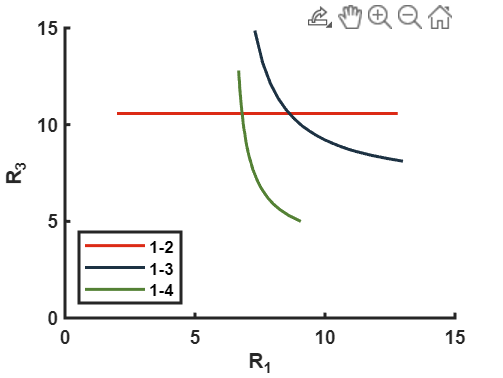


plot(x3,y3,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')





set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','southwest');

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

